# Planet trajectory prediction

t1 = 0:.05:10; % time
x1 = cos(2*pi*t1);
y1 = sin(2*pi*t1);
t2 = t1;%.*1.01.^t1; % time speed ups
x2 = cos(1.5*pi*t2);
y2 = sin(1.5*pi*t2);

theta = pi/3;
R = @(theta) [cos(theta) -sin(theta); sin(theta) cos(theta)];

data = [R(pi/3) * [1.25*x1; 0.5*y1]; R(pi/6) * [x2; 0.5*y2]];
p = 0.75;

mid_point = round((length(data) - 1) * p);
train_t1 = t1(1:mid_point);
test_t1 = t1(mid_point:end-1);
test_t1_fine = t1(mid_point):0.01:t1(end-1);

train_t2 = t2(1:mid_point);
test_t2 = t2(mid_point:end-1);
test_t2_fine = t2(mid_point):0.01:t2(end-1);

train_input  = data(:, 1:mid_point);
train_output = data(:, 2:(mid_point + 1));
test_input   = data(:, mid_point:(end-1));
test_output  = data(:, (mid_point + 1):end, :);

## Construct the network

net = Network();
Nres = 5;
%lID(1) = net.addLayer(1,                    'bias',     struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '1.0')); 
lID(2) = net.addLayer(size(train_input, 1), 'input',    struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '1.0'));
lID(3) = net.addLayer(size(train_output,1), 'output',   struct('nodeType', 'linear', 'leakageInit', 'constant', 'leakageVal', '1.0'));
lID(4) = net.addLayer(Nres,                  'layer',     struct('nodeType', 'tanh',   'leakageInit', 'constant', 'leakageVal', '1.0'));

net.setConnection(lID(2), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(2), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(1), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(1), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(4), lID(3), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 1.0));
net.setConnection(lID(4), lID(4), struct('initType', 'randn', 'connectivity', 1.0, 'radius', 0.1));


%net.visualize();

## Train the network

boltrain = BatchOutputLayerTrain();
initLen = 50;
tic
X = boltrain.train(net, train_input, train_output, initLen, 'ridge2');
toc 

Elapsed time is 0.016811 seconds.


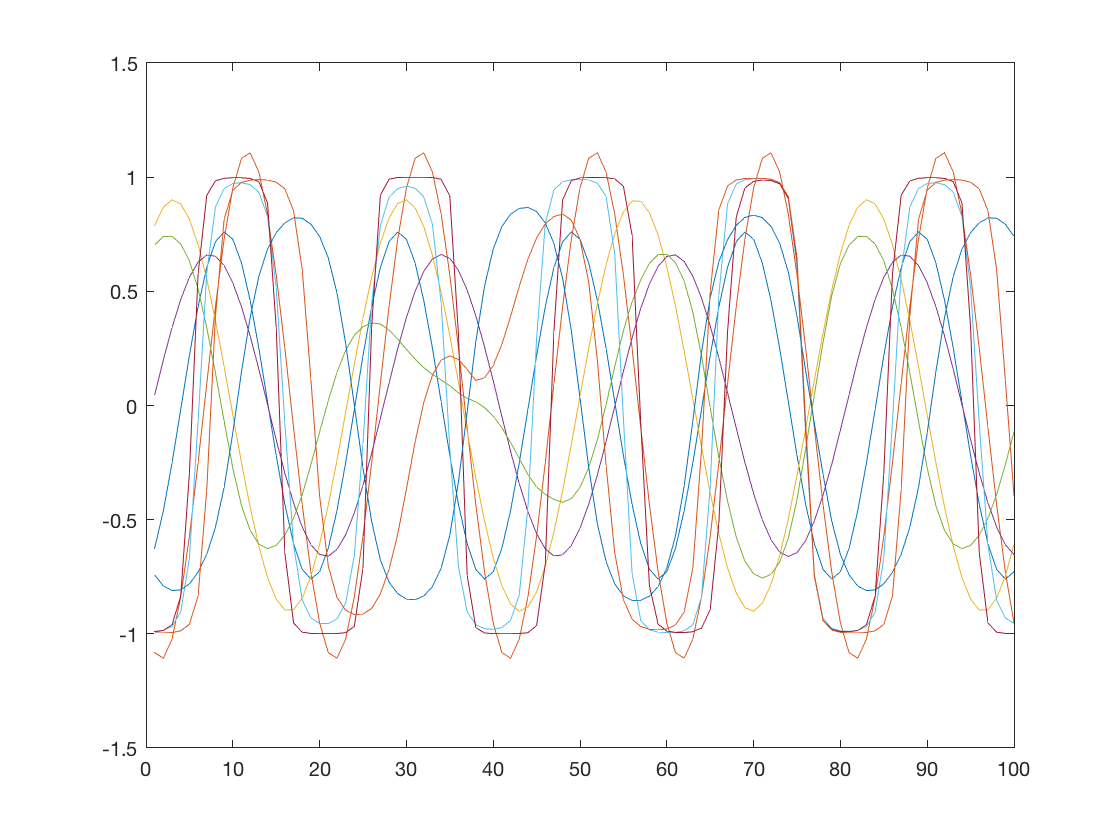

figure, plot(X')

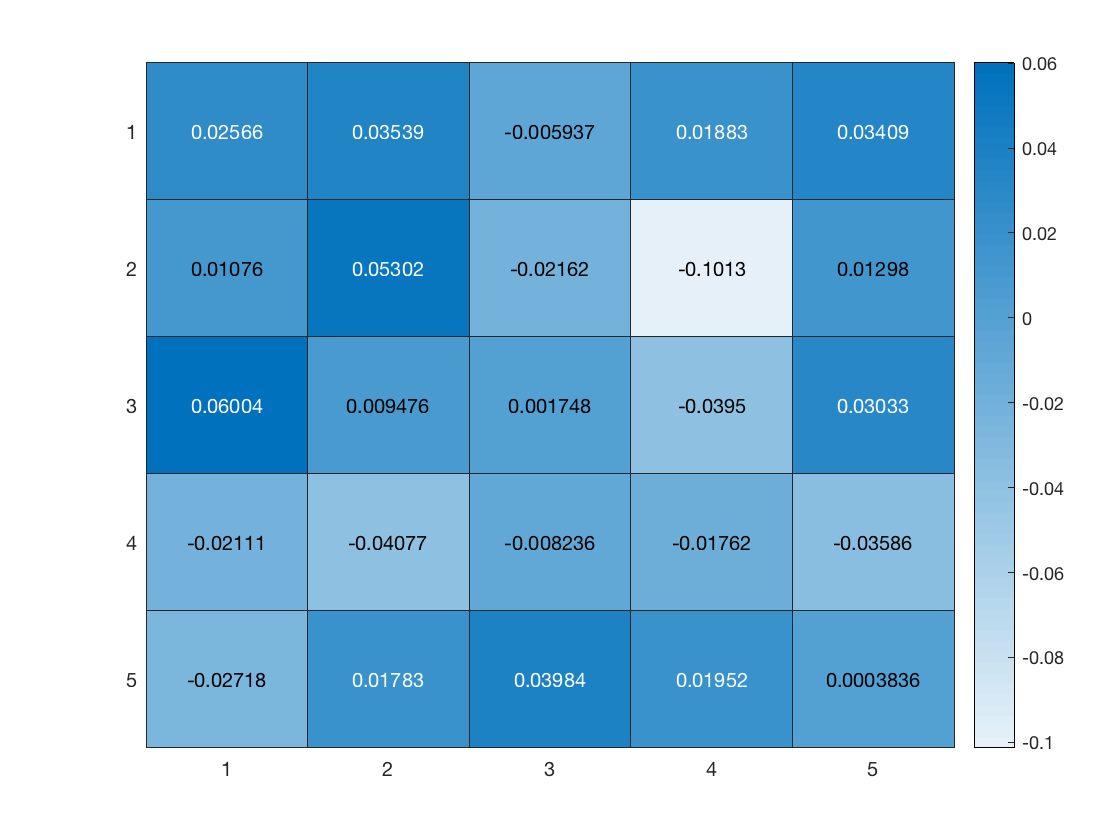

figure, heatmap(net.Weights(end-Nres + 1:end, end-Nres + 1:end));

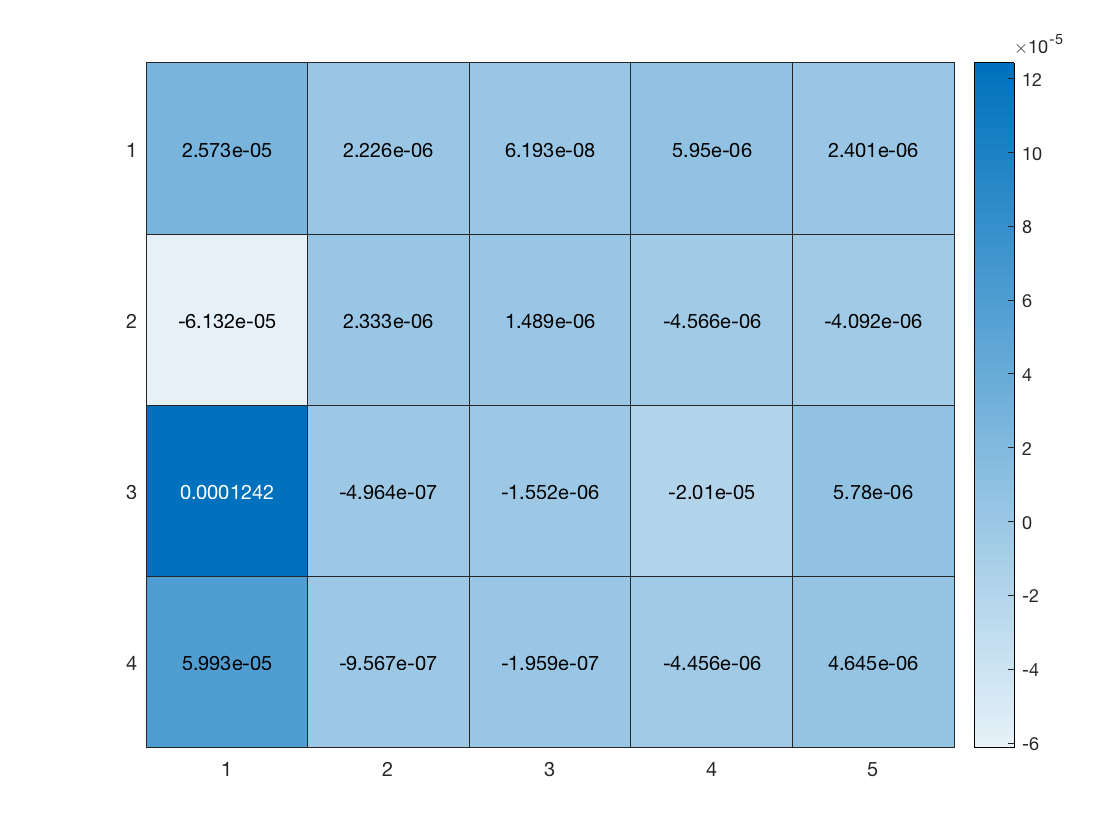

figure, heatmap(net.getWeights(lID(4), net.getIdByType('output')));

## Generate/Predict

tic
net.rememberStates();
Y = net.generate(test_input(:, 1), size(test_input, 2));
net.recallStates();
toc 

Elapsed time is 0.013508 seconds.



disp(['RMSE: ', num2str(norm(Y - test_output)/sqrt(length(Y)))]);

RMSE: 0.00019752


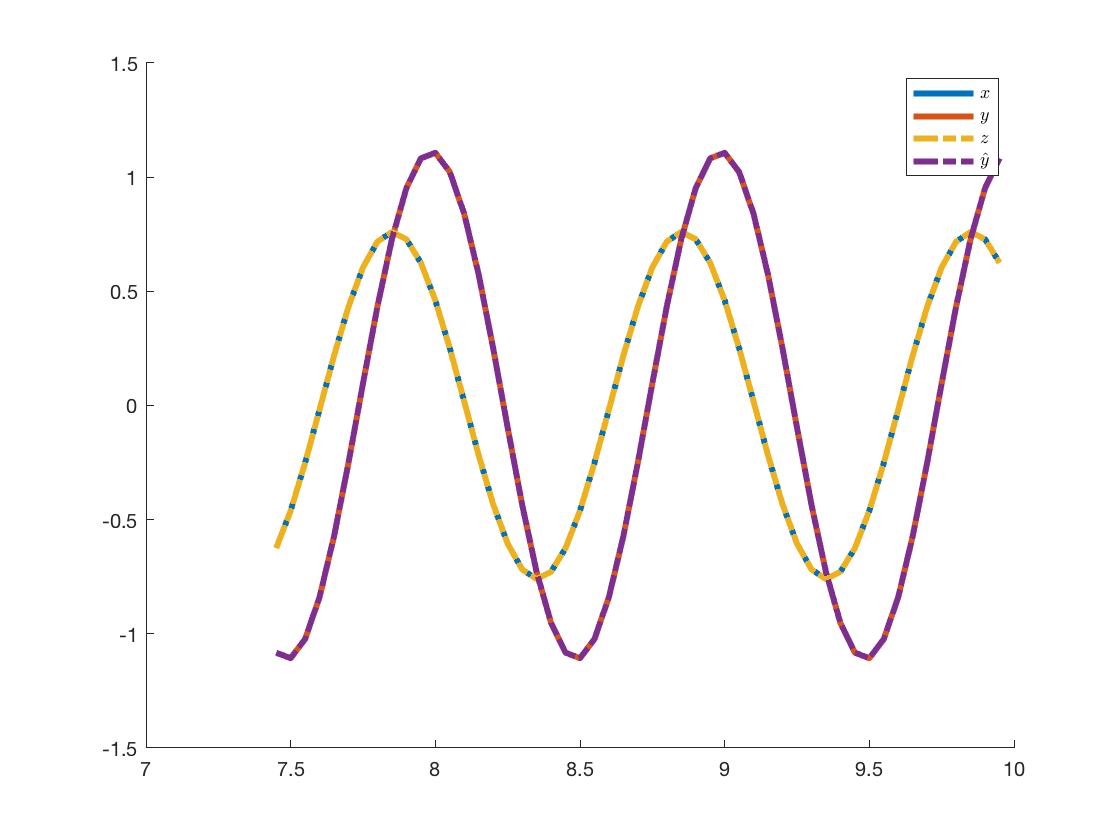

%disp(['NRMSE: ', num2str(NRMSE(y, test_output))]);

figure, hold on;
plot(test_t1, test_output(1:2, :)', 'linewidth', 3);
plot(test_t1, Y(1:2, :)','-.', 'linewidth', 3);
legend({'$x$', '$y$', '$z$', '$\hat{y}$'}, 'interpreter', 'latex');

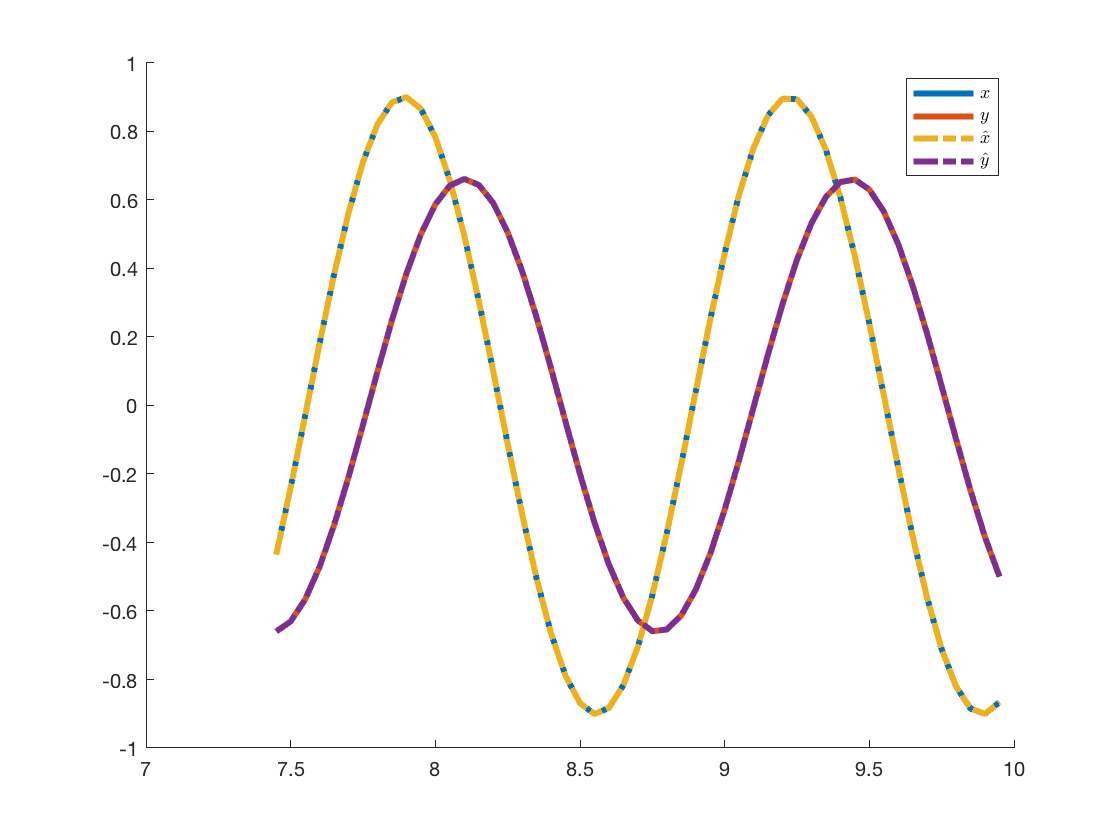


figure, hold on;
plot(test_t2, test_output(3:4, :)', 'linewidth', 3);
plot(test_t2, Y(3:4, :)','-.', 'linewidth', 3);
legend({'$x$', '$y$', '$\hat{x}$', '$\hat{y}$'}, 'interpreter', 'latex');

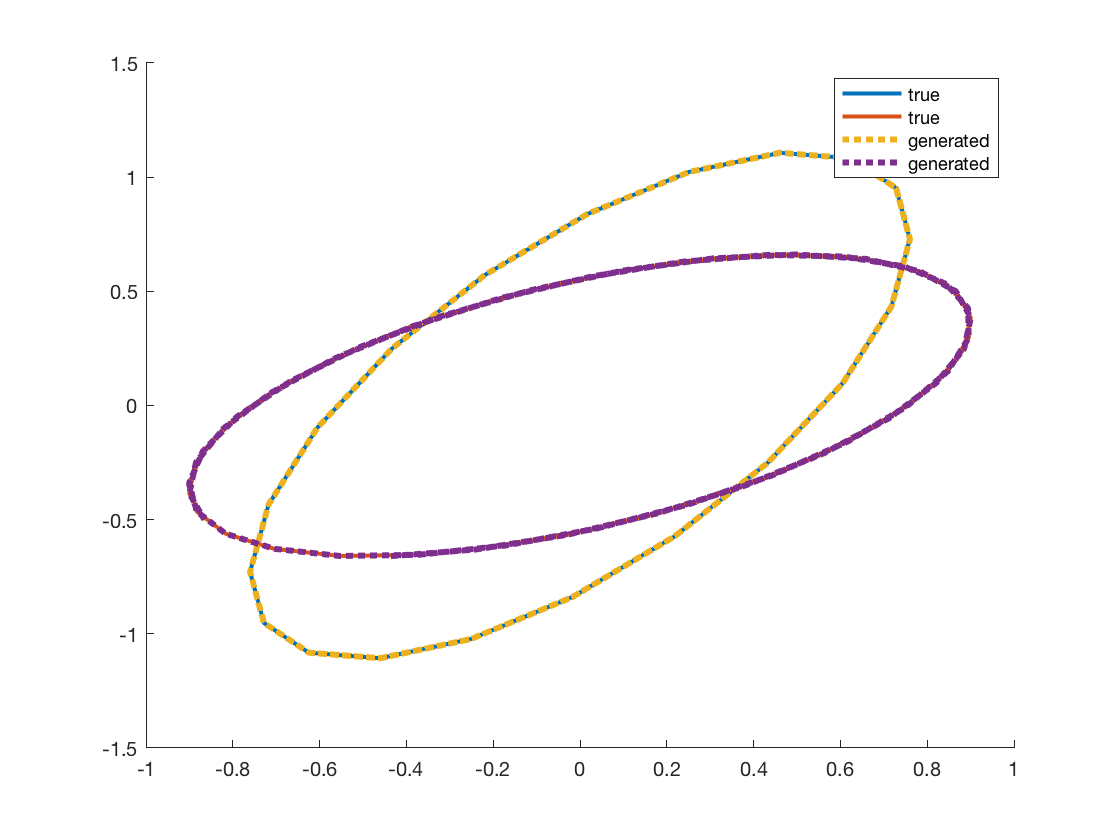


figure, hold on;
plot(test_output(1,:), test_output(2,:), 'linewidth', 2);
plot(test_output(3,:), test_output(4,:), 'linewidth', 2);
plot(Y(1,:), Y(2,:), ':', 'linewidth', 3);
plot(Y(3,:), Y(4,:), ':', 'linewidth', 3);
legend({'true', 'true', 'generated', 'generated'});

%axis equal

